# Init

close all
clear all
clc

## Error on airspeed depending on error on angle of attack

Equation used to evaluate airspeed using lift coefficient


$$\sum F = m\,a\\
\frac{1}{2}\rho S V^2(C_{L_{0}}+C_{L_{\alpha}}\alpha) = m a_z\\
V =( \frac{-2ma_z}{\rho S (C_{L_{0}}+C_{L_{\alpha}}\alpha)})^{\frac{1}{2}}\\
V = (\frac{K1}{K2+K3\alpha})^{\frac{1}{2}}\\
\text{where:  } K1 = \frac{-2ma_z}{\rho S}, K2=C_{L_{0}}, K3 = C_{L_{\alpha}}
$$



$$\frac{\partial V}{\partial \alpha} = \frac{-K3\frac{K1}{K2+K3\alpha}^{(3/2)}}{2+K1}$$


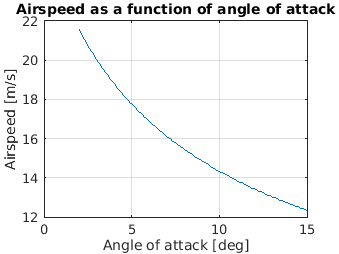

%% Evaluating airspeed using angle of attack
m = 6.5; %kg
rho = 1.225; %kg/m^3
b = 1.797;
c = 0.244;
S = b*c;
AR = b/c;
a_z = -9.81;

CL_alpha = 4.60658; %based on XFLR5 %2*pi*(AR/(2+AR));
CL_0 = 0.35;
dalpha = 0.1;
alpha = deg2rad([2:dalpha:15]);


V =sqrt(-(2.*m.*a_z)./(rho.*S.*(CL_0+alpha.*CL_alpha)));

figure
plot(rad2deg(alpha),V)
xlabel('Angle of attack [deg]')
ylabel('Airspeed [m/s]')
title('Airspeed as a function of angle of attack')
grid on

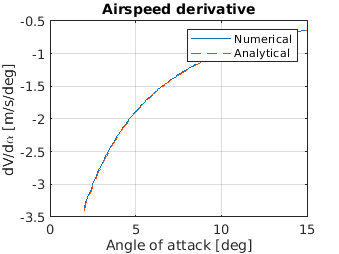


figure
plot(rad2deg(alpha(1:end-1)),((V(1:end-1)-V(2:end))./(alpha(1:end-1)-alpha(2:end))*2*pi/180))
xlabel('Angle of attack [deg]')
ylabel('dV/d\alpha [m/s/deg]')
title('Airspeed derivative')
grid on

K1 = -2*m*a_z/(rho*S);
K2 = CL_0;
K3 = CL_alpha;
dVdaoa = -K3.*(K1./(K2+K3.*alpha)).^(3/2)/(2*K1);
hold on
plot(rad2deg(alpha),dVdaoa*(2*pi/180),'--')
legend('Numerical','Analytical')
grid on

## Alpha estimation using gamma

Equation used to estimate alpha (assuming no vertical wind)


$$\alpha = \theta-\gamma\\
\gamma = asin(\frac{\dot{h}}{V_t})
$$


Hence:


$$\alpha = \theta-asin(\frac{\dot{h}}{V_t})$$



$$\frac{\partial \alpha}{\partial V_t} = \frac{\dot{h}}{V_t^2\sqrt{1-\frac{\dot{h}^2}{V_t^2}}}$$



$$\frac{\partial \alpha}{\partial \dot{h}} = -\frac{1}{V_t\sqrt{1-\frac{\dot{h}^2}{V_t^2}}}$$


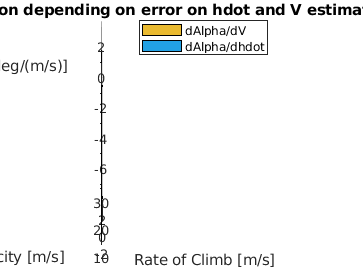

%% Estimating alpha using rate of climb

hdot = [-2.5:0.1:2.5]; %[m/s] 500fpm to -500fpm
V = [10:0.5:30]; %[m/s]

[HDOT,VELOCITY] = meshgrid(hdot,V);

dalpha_dtheta = 1;
dalpha_dv = HDOT./(VELOCITY.^2.*(1-(HDOT.^2./VELOCITY.^2)).^(1/2));
dalpha_dhdot = -1./(VELOCITY.*(1-(HDOT.^2./VELOCITY.^2)).^(1/2));

figure
surf(HDOT,VELOCITY,rad2deg(dalpha_dv))
xlabel('Rate of Climb [m/s]')
ylabel('Velocity [m/s]')
zlabel('Error [deg/(m/s)]')
hold on
surf(HDOT,VELOCITY,rad2deg(dalpha_dhdot))
legend('dAlpha/dV','dAlpha/dhdot')
title('Error on alpha estimation depending on error on hdot and V estimation')

Analysis

- More effect if h_dot wrongly estimated

- If h_dot >0: + error on V --> + error on alpha --> - error on V_est 

- If h_dot <0: + error on V --> - error on alpha --> + error on V_est

- RISK of DIVERGENCE with descent... 

## Overall Divergence


$$\frac{\partial V}{\partial Vt} = \frac{\partial V}{\partial \alpha} \frac{\partial \alpha}{\partial V_t}$$



$$\frac{\partial \alpha}{\partial V_t} = \frac{\dot{h}}{V_t^2\sqrt{1-\frac{\dot{h}^2}{V_t^2}}}$$



$$\frac{\partial V}{\partial \alpha} = \frac{-K3\frac{K1}{K2+K3\alpha}^{(3/2)}}{2+K1}$$



$$\text{where:  } K1 = \frac{-2ma_z}{\rho S}, K2=C_{L_{0}}, K3 = C_{L_{\alpha}}$$


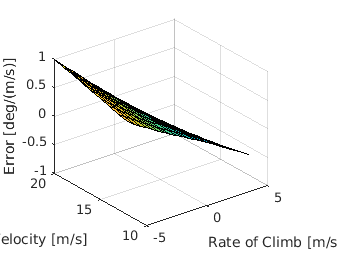


hdot = [-5:0.5:5]; %m/s
V = [12:1:20]; %m/s

[HDOT,VELOCITY] = meshgrid(hdot,V);

K1 = -2*m*a_z/(rho*S);
K2 = CL_0;
K3 = CL_alpha;

alpha = (((VELOCITY.^2/K1).^(-1))-K2)./K3;

dVdaoa = -K3.*(K1./(K2+K3.*alpha)).^(3/2)/(2*K1);

dalpha_dv = HDOT./(VELOCITY.^2.*(1-(HDOT.^2./VELOCITY.^2)).^(1/2));

dVdVt = dVdaoa.*dalpha_dv;


figure
surf(HDOT,VELOCITY,dVdVt)
xlabel('Rate of Climb [m/s]')
ylabel('Velocity [m/s]')
zlabel('Error [m/s / m/s]')